load mtlb;
targetFs = 50000;
X = resample(mtlb,targetFs,Fs);
Fs = targetFs;
X = [[X X];zeros(1*Fs,2)]./max(X,[],"all")/2;

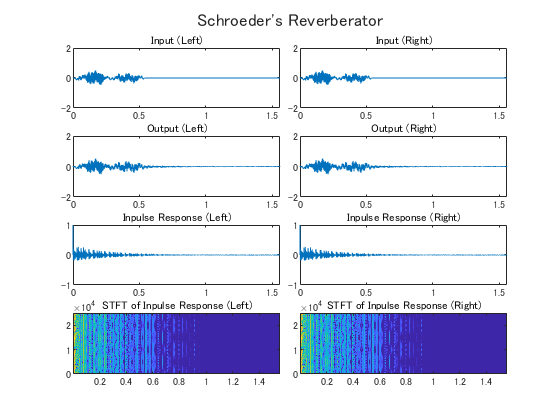

p = CR_Schroeders();

p.T      = 2;
p.drymix = 1;
p.wetmix = 0.2;

test_reverb(p, X, Fs);

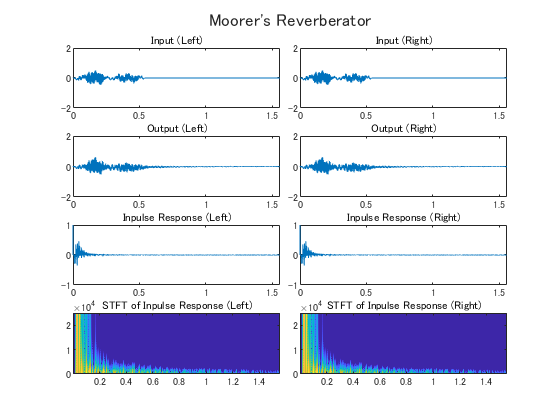

p = CR_Moorers();

p.g =      0.95;
p.drymix = 1;
p.wetmix = 0.2;
p.damp   =  1.09;

test_reverb(p, X, Fs);

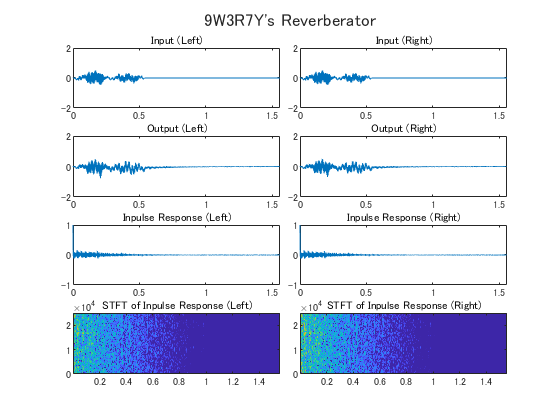

p = Q_Reverb();
p.T      = 2;
p.drymix = 1;
p.wetmix = 0.2;
p.W      = 0.2;

test_reverb(p, X, Fs);